# 802.11b SEM (dB scale)

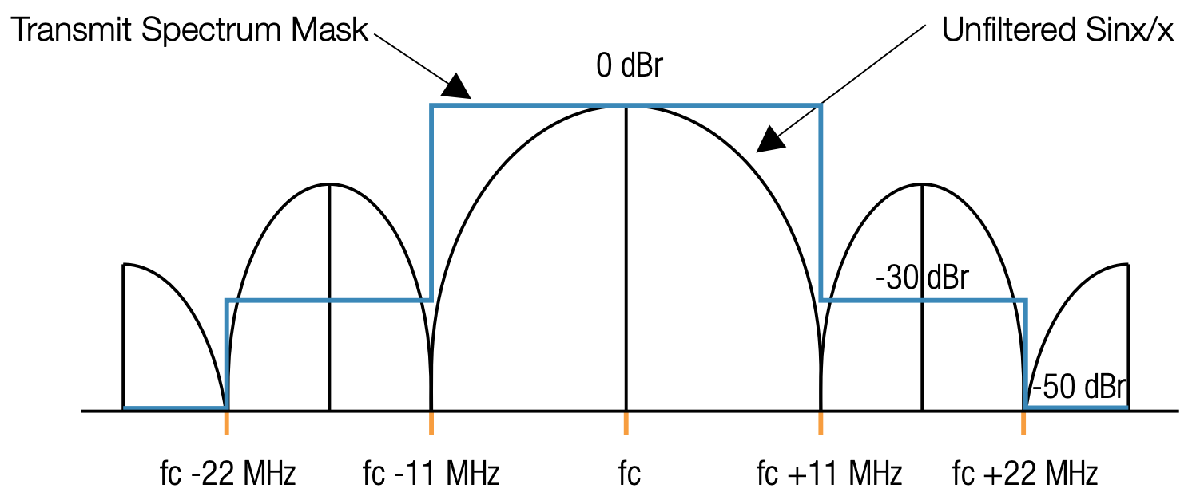

### Normalized frequency $f\in [-0.5, 0.5]$


$$f \text{(cycles/sample)} = \frac{F\text{(cycles/sec)}}{ F_s\text{(sampling rate)}} = \frac{F}{2B\text{(bandwidth)}}$$


### Definition of the 20 Mhz 802.11b SEM function in $F$ (MHz)


$$\mathrm{SEM}(F) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |F| \leq 11\\
-30 & \mbox{if } \quad 11\leq |F| \leq 22\\
-50 & \mbox{if } \quad |F| \geq 22\\
\end{array}\right.$$


### Definition of the 802.11ac SEM in $f, B$ (MHz)


$$\mathrm{SEM}(F) = \left\{\begin{array}{ll}
0 & \mbox{if } \quad 0\leq |f| \leq \frac{11}{2B}\\
-30 & \mbox{if } \quad \frac{11}{2B}\leq |f| \leq \frac{22}{2B}\\
-50 & \mbox{if } \quad |f| \geq \frac{22}{2B}\\
\end{array}\right.$$


function SEM = SEM_b(delta_f, f_range, B, channel_size)
% Generate only the positive part
f = f_range(1):delta_f:f_range(2);
SEM = zeros(length(f), 1);

W = 2*B;

if channel_size == 20   % on_ratio = 0.5485
    for idx = 1:length(f)
        if f(idx) < 11/W
            % freq: 0~11 MHz
            SEM(idx) = 0;
        elseif f(idx) < 22/W
            % freq: 11~22 MHz
            SEM(idx) = -30;
        else
            % freq: >22 MHz
            SEM(idx) = -50;
        end
    end

% Generate the negative part
SEM = [flipud(SEM); SEM(2:end)];
end